# Ali Razani

## 40205984

### HW5

#### Q2

# الف

## یافتن فاکتورهای بهم اول

الگوریتم زیر جهت یافتن اینم فاکتورها نوشته شده و نحوه عملکرد آن بصورت استفاده از سمبل ها و دستورات تولباکس محاسبات نمادین است. این الگوریتم راه حل جزوه را دنبال میکند و مراحل پیشرفت نمایش داده خواهند شد. در اینجا تغییراتی دیگر اعمال شده است، فرض کردیم کنترل کننده یک انتگرال گیر غیرقابل تغییر دارد و برای تغییر نکردن آن، به تابع تبدیل اعمال شده و سراغ بخش های دیگر طراحی رفته ایم. دلیل اضاف کردن این انتگرال گیر این بوده است که سیستم خود نوع اول بوده است و خطای پاسخ پله صفر خواهد شد، و با اضاف کردن یک انتگرال گیر خطای پاسخ به شیب را نیز صفر کرده ایم

syms s x
P = 1 / (s*(s^2+0.2*s+1));
[, X, N, MY] = euclid_tf(P/s);

poles are:
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.1000 + 0.9950i
  -0.1000 - 0.9950i
we should change variable (s = (1-x)/x), so new tf is
              4
           5 x
-------------------------
       2     2
(x - 1)  (9 x  - 9 x + 5)

nx + my = 1
n is
   4
5 x

m is
       2     2
(x - 1)  (9 x  - 9 x + 5)

step 1
n = q1 * m + r1
q1 is
5
-
9

r1 is
             2
    3   160 x    95 x   25
15 x  - ------ + ---- - --
           9       9     9

step 2
m = q2 * r1 + r2
q2 is
3 x   49
--- - --
 5    45

r2 is
     2
511 x    473 x   160
------ - ----- + ---
  81       81     81

step 3
r 1 = * r 2 * q 3 + r 3
q 3 is
1215 x   161145
------ - ------
  511    261121

r 3 is
588870 x   407025
-------- - ------
 261121    261121

step 4
r 2 = * r 3 * q 4 + r 4
q 4 is
133432831 x   45483883627
----------- - -----------
  47698470    69353575380

r 4 is
163200625
---------
171243396

finished
Q * R = MN * [n; m]
Q is
/     1,           0,                    0,             0 \
|         

## یافتن کنترل کننده

پس از یافتن موارد مورد نیاز، کنترل کننده بصورت زیر خواهد بود


$$
\[
C = \frac{X + MQ}{Y - NQ}
\]

\end{document}
$$


که در آن متغیر کیو هنوز یافت نشده است. دیگر مقادیر از تجزیه زیر بدست آمده اند. دیگر ماتریس ها یافت شده و در قسمت قبل نمایش داده شده اند


$$
\[
G = \frac{N}{M}, \quad NX + MY = 1
\]

\end{document}
$$


تحت کنترل فوق، تابع تبدیل حساسیت و مکمل حساسیت بصورت زیر هستند


$$$$S = M(Y - NQ)$$
$$



$$$$T = N(X + MQ)$$$$


برای تعقیب شیب بایستی


$$$$ N(s)[X(s)+M(s)Q(s)] for( s=0) = 1$$$$


و برای دفع اغتشاش بایستی


$$$$$N(2j)[Y(2j)-N(2j)Q(2j)]=0$$


و تابع تبدیل کیو باید شرایط بالا را ارضا کند

N0 = limit(N,s,0)

$$N0 = 5$$

X0 = limit(X,s,0)

$$X0 = \frac{1}{5}$$

M0 = limit(M,s,0)

$$M0 = 0$$

با توجه به اینکه در فرمول تابع مکمل حساسیت ضریب کیو صفر شده و ضرب دیگر ضرایب یک شده است، این تابع تبدیل همواره شیب را تعقیب میکند بدون آن که خطای حالت دائم رخ دهد. بنابراین در اینجا محدودیتی بر کیو اعمال نشد

حال طبق تابع تبدیل حساسیت در فرکانس مد نظر

N2 = subs(N,s,2*1j)

$$N2 = -\frac{7}{125}+\frac{24}{125}\,\mathrm{i}$$

X2 = subs(X,s,2*1j)

$$X2 = -\frac{5199}{390625}+\frac{552968}{390625}\,\mathrm{i}$$

M2 = subs(M,s,2*1j)

$$M2 = -\frac{228}{625}+\frac{1496}{625}\,\mathrm{i}$$

Y2 = subs(Y,s,2*1j)

$$Y2 = -\frac{3569}{78125}-\frac{40942}{78125}\,\mathrm{i}$$


$$Q(2j)=-X(2j)/M(2j)$$


Q_2j = vpa(Y2/N2, 4)

$$Q\_2j = -2.452+0.953\,\mathrm{i}$$

Ks = imag(Q_2j) / 2;
K0 = real(Q_2j);
Q = Ks * s + K0;
vpa(Q, 3)

$$ans = 0.476\,s-2.45$$

و بدین صورت کیو یافت شد. حال طبق رابطه ساخت کنترل کننده و در نظر گرفتن این حقیقت که کنترل کننده دارای یک انتگرال گیر بود

C = simplify((X + M * Q) / (Y - N * Q) / s);
vpa(C, 2)

$$ans = \frac{1.2e+32\,s^{5}-4.7e+32\,s^{4}+7.6e+31\,s^{3}-5.8e+32\,s^{2}+8.0e+31\,s+1.0e+31}{s\,\left(1.0e+31\,s^{4}+7.8e+31\,s^{3}+2.5e+32\,s^{2}+3.1e+32\,s+8.6e+32\right)}$$

ادعا میشود که کنترل کننده بالا از عهده وظایف برآید

سیستم حلقه بسته را بدین صورت می سازیم

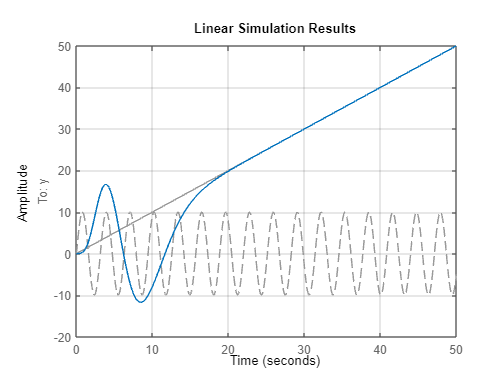

Cs = sym2tf(C);
Ps = sym2tf(P);
Cs.InputName = {'e'};
Cs.OutputName = {'u'};
sum_dis = sumblk('dis_u = u + dis');
Ps.InputName = {'dis_u'};
Ps.OutputName = {'y'};
sum_e = sumblk('e = r - y');
ins = {'r'}; ins(2,:) = {'dis'};
cls = connect(Ps, Cs, sum_e, sum_dis, ins, {'y'});
t = linspace(0, 50, 500);
dist = 10 * sin(2*t);
figure
lsim(cls, [t;dist], t);
grid on

دیده میشود که اغتشاشی بزرگ توانست در عرض بیست ثانیه دفع شود. اگر این اغتشاش را کوچکتر کنید، زودتر دفع خواهد شد و دامنه آن کوچکتر خواهد بود

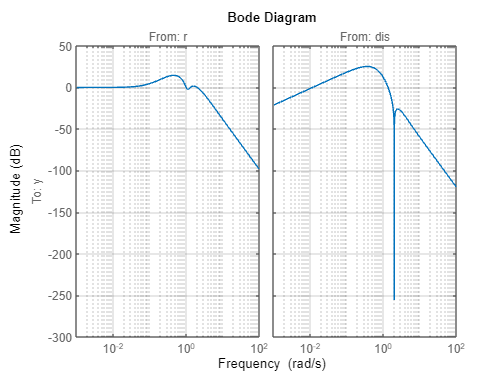

figure
bodemag(cls)
grid on

رسم بودی نیز پیشنهاد میدهد که خطای پاسخ پله نیز صفر میشود و اغتشاش فرکانس مذکور صفر خواهد شد 